# Load data

clear
load('Assignment_Data_SC42145.mat');
G = tf(FWT(1,1:2));

## Weight design

w_c1 = 0.3e-3;
w_c2 = 1e-1;
tau_pen = tf([w_c1],[1,w_c1]);
beta_pen = tf([1,0],[1,w_c2]);

Wu = [beta_pen 0; 0 tau_pen];
w_cp = 0.2*2*pi;
Wp = tf([1/1.8, w_cp], [1, w_cp*1e-4]);

%Wp = tf([1/1.5, 0.25], [1, 0.25*1e-3]);
% Wp = tf([1/1.1, 1*pi], [1, 1*pi*1e-4]);

plot weights

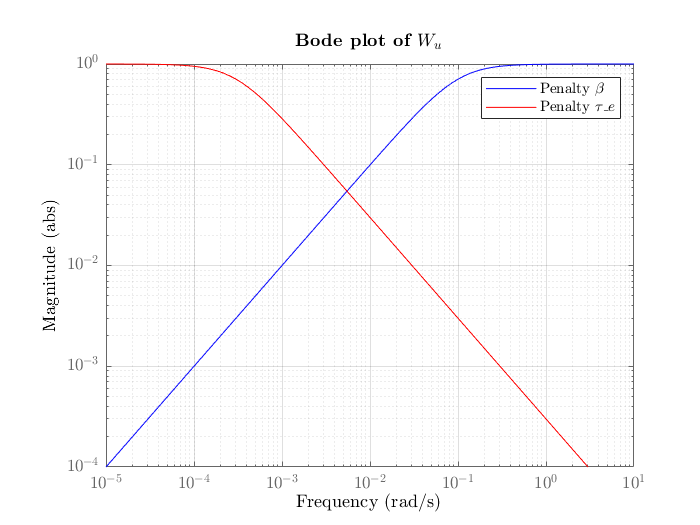

clf;
set(groot,'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex'); 
set(groot, 'defaultLegendInterpreter','latex');
figure();
bodemag(beta_pen, 'blue');
hold on
%bodemag(tau_pen);
latex_bodemag(tau_pen, "$W_u$", 'red')
legend("Penalty $\beta$", "Penalty ${\tau}_{e}$")
set(gcf,'renderer','painters');
saveas(gcf, 'Figures/ch3_mimo_weights_u_filter.eps',  'epsc')

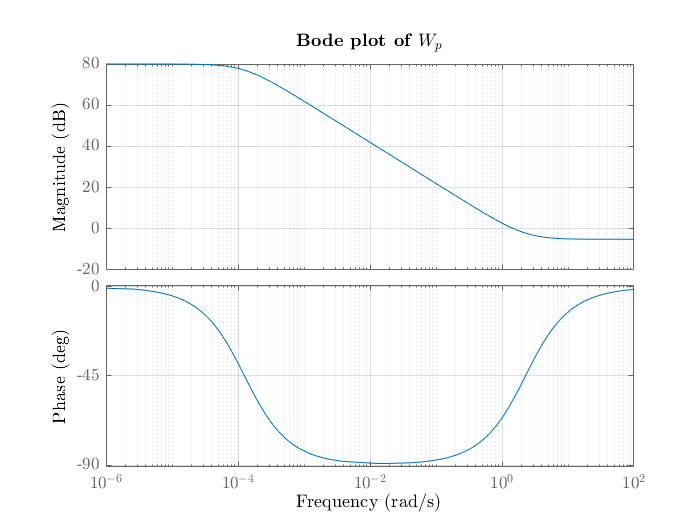


figure()
%bode(Wp)
latex_bode(Wp, "$W_p$")
set(gcf,'renderer','painters');
saveas(gcf, 'Figures/ch3_mimo_weights_p_filter.eps',  'epsc')

## H-infinity Controller Synthesis

P11=[Wp; zeros(size(Wu,2),size(Wp,1))]; P12=[Wp*(G); Wu]; P21=eye(size(Wp)); P22=G;
P = [P11 P12; P21 P22];

% H-infinity norm synthesis
[K, CL, gamma,syn_info] = hinfsyn(P, 1, 2); %2 inputs, 1 output
H_inf_norm_CL = gamma

H_inf_norm_CL = 0.8622


%define in/outputnames of K
K.InputName = {'dOmega'};
K.OutputName = {'Beta (deg)'; 'tau_e (Nm)'};
dOmega_sum = sumblk('dOmega = r - Omega (rad/s)');


%build closed loop transfer function
%first connect sum block with K by connecting inputs and outputs
%the new model has inputs [r,Omega,z] and outputs [beta, tau]
ref_tf = connect(dOmega_sum, -K,  {'r';'Omega (rad/s)'},{'Beta (deg)';'tau_e (Nm)'});
%these outputs are connected as inputs of the plant
%the inputs of the connected system are the exogenous inputs [r,V]
%we would like to monitor [r,z,Omega,tau,V], so these are the chosen outputs
outputs_ = {'r';'V (m/s)';'Omega (rad/s)'; 'Beta (deg)';'tau_e (Nm)'};
closed_loop = connect(ref_tf, FWT, {'r';'V (m/s)'}, outputs_);

closed_loop = minreal(closed_loop);

8 states removed.


## plotting of synthesis results (q3.4)

H_inf_norm_CL

H_inf_norm_CL = 0.8622

tf2latex(K)

d$\omega$ \to $\beta$ (deg)&=\frac{0.06973\,s^{19}+3931.0\,s^{18}+14660.0\,s^{17}+1.448e+5\,s^{16}+4.66e+5\,s^{15}+1.867e+6\,s^{14}+4.974e+6\,s^{13}+9.493e+6\,s^{12}+1.835e+7\,s^{11}+1.391e+7\,s^{10}+5.744e+6\,s^9+1.924e+6\,s^8+5.088e+5\,s^7+97520.0\,s^6+17670.0\,s^5+2010.0\,s^4+214.0\,s^3+12.86\,s^2+0.003223\,s+2.023e-7}{s^{20}+56370.0\,s^{19}+78330.0\,s^{18}+1.883e+6\,s^{17}+2.264e+6\,s^{16}+2.113e+7\,s^{15}+2.15e+7\,s^{14}+8.193e+7\,s^{13}+6.762e+7\,s^{12}+2.62e+7\,s^{11}+8.848e+6\,s^{10}+2.289e+6\,s^9+3.972e+5\,s^8+77730.0\,s^7+6387.0\,s^6+921.4\,s^5+15.45\,s^4+0.2264\,s^3+8.385e-5\,s^2+6.711e-9\,s-3.53e-14}
d$\omega$ \to $\tau_e$ (Nm)&=\frac{1.379e+7\,s^{19}+2.599e+7\,s^{18}+4.711e+8\,s^{17}+7.833e+8\,s^{16}+5.468e+9\,s^{15}+7.85e+9\,s^{14}+2.287e+10\,s^{13}+2.67e+10\,s^{12}+1.526e+10\,s^{11}+5.864e+9\,s^{10}+1.83e+9\,s^9+4.386e+8\,s^8+8.316e+7\,s^7+1.358e+7\,s^6+1.493e+6\,s^5+1.493e+5\,s^4+7080.0\,s^3+3.872\,s^2+0.0006388\,s+3.315e-8}{s^{20}+56370.0\,s^{19}+78330.0\,s^{18}+1.883e

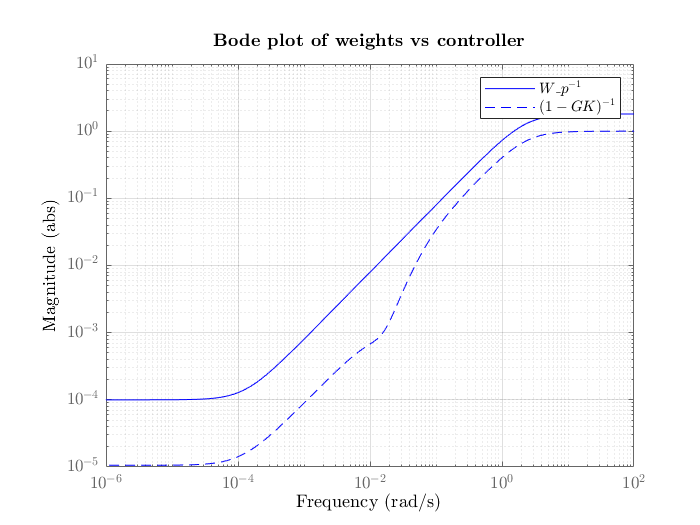


figure(); bodemag(inv(Wp),'blue'); hold on;
S = 1/(1-G*K);% bodemag(S, ['blue','--'])
latex_bodemag(S," weights vs controller",['blue','--']);
legend("${W_p}^{-1}$", "$(1-GK)^{-1}$")
set(gcf,'renderer','painters');
saveas(gcf, 'Figures/ch3_weights_vs_controller_p.eps',  'epsc')

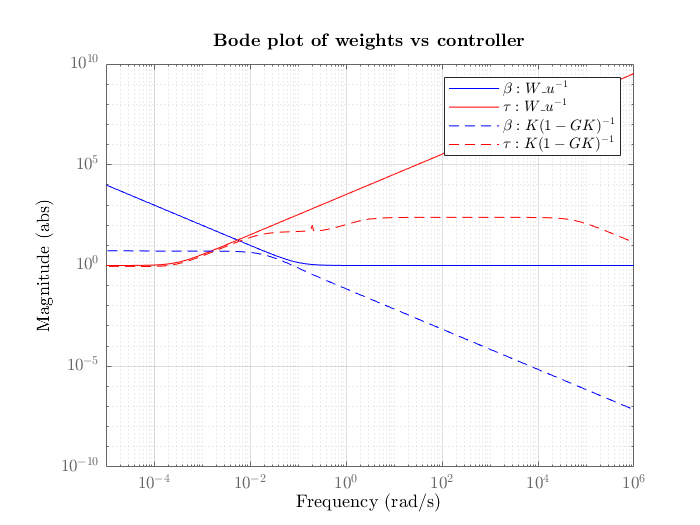


figure(); bodemag(inv(Wu(1,1)) ,'blue'); hold on;
bodemag(inv(Wu(2,2)), 'red');
bodemag(K(1,:)/(1-G*K), ['--', 'blue']); %Wu(1,1)
latex_bodemag(K(2,:)/(1-G*K), "weights vs controller",['--', 'red']); %*Wu(2,2)

legend("$\beta: W_{u}^{-1}$", "$\tau: W_{u}^{-1}$", "$\beta: K(1-GK)^{-1}$", "$\tau: K(1-GK)^{-1}$");
set(gcf,'renderer','painters');
saveas(gcf, 'Figures/ch3_weights_vs_controller_u.eps',  'epsc')

## Performance assessment

using step response

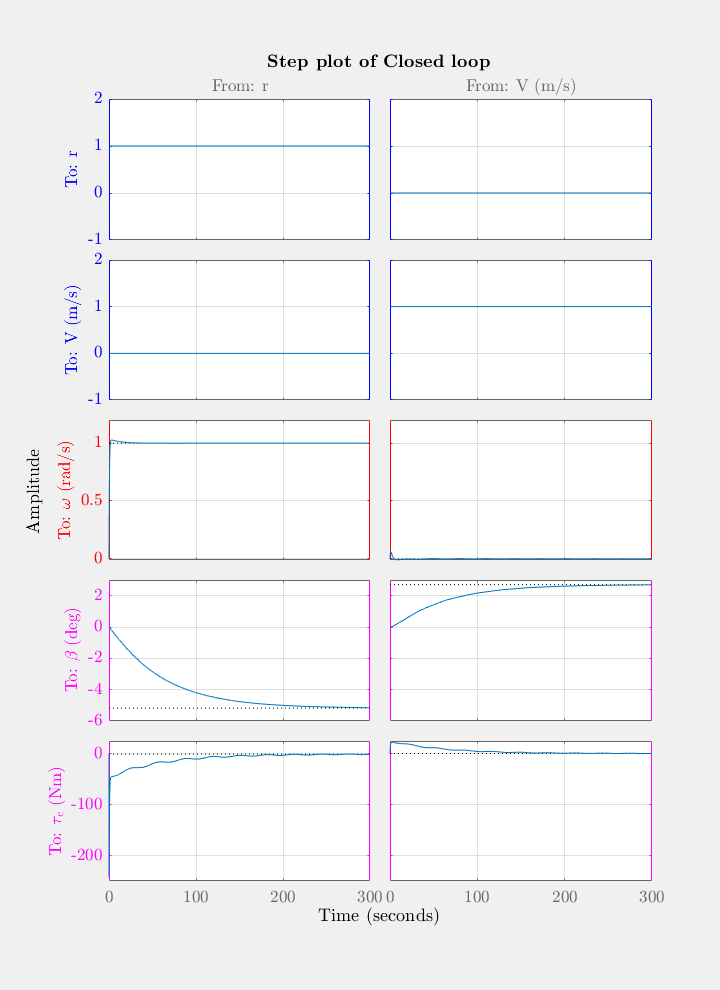

clf

figsize = [0,0,6,4 *6];

figure('units','inch','position',figsize);

latex_step(closed_loop, "Closed loop", 300)
%[Y_sim, T_sim] = step(closed_loop);
axs= findobj(allchild(gcf), 'flat', 'Type', 'axes');

%exogenous inputs
axs(end).YColor='Blue';
axs(end-1).YColor='Blue';
axs(6).YColor='Blue';
axs(5).YColor='Blue';

%outputs
axs(end-2).YColor='Red';
axs(4).YColor='Red';

%control inputs
axs(8).YColor='Magenta';
axs(7).YColor='Magenta';
axs(3).YColor='Magenta';
axs(2).YColor='Magenta';

set(gcf,'Visible','on')

## Time Domain Simulation using wind data

Plot wind data

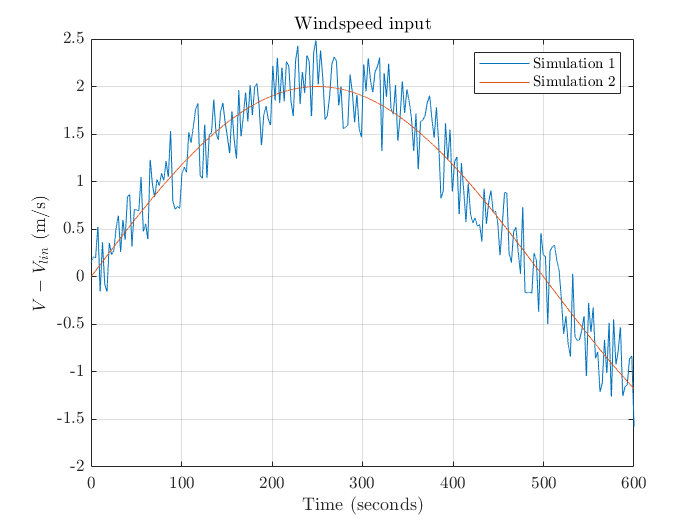

figure()
plot(Wind_Data)
hold on
t_d = Wind_Data.Time;
plot(t_d, sin(t_d*(2e-3*pi))*2);
grid on
legend("Simulation 1", "Simulation 2")
set(groot,'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex'); 
xlabel("Time (seconds)", 'interpreter', 'latex')
ylabel("$V-V_{lin}$ (m/s)", 'interpreter', 'latex')
title("Windspeed input", 'interpreter', 'latex')
set(gcf,'renderer','painters');
saveas(gcf, 'Figures/ch3_wind_input.eps',  'epsc')

Perform simulation

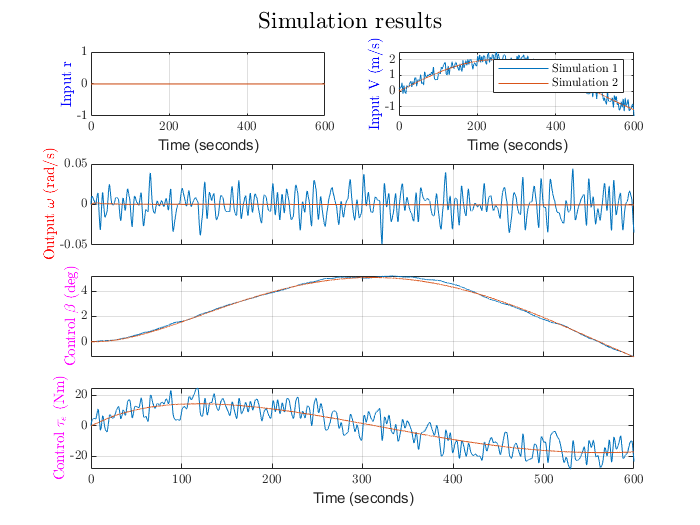

%to resample the input to evenly spaced timesteps:
figure(1)
clf

dt = mean(diff(t_d));
t = min(t_d):dt:max(t_d);
u_1 = resample(Wind_Data,t).Data';
u_2 = sin(t*(2e-3*pi))*2;
results = latex_lsim(closed_loop(:,2), u_1,t, [2,1,2],u_2);

set(gcf,'renderer','painters');
saveas(gcf, 'Figures/ch3_sim_output.eps',  'epsc')